## Metrics included with Warp Factory

Now that you understand the basics of metrics, here are some existing metrics to explore.

## Standard Metrics

### Minkowski

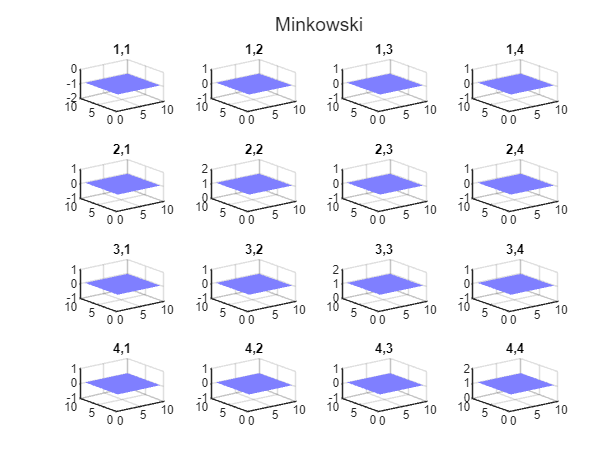

%% Minkowski
gridSize = [1 10 10 10];
gridScaling = [1 1 1 1];
Metric = metricGet_Minkowski(gridSize, gridScaling);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,1),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name)

### Schwarzschild

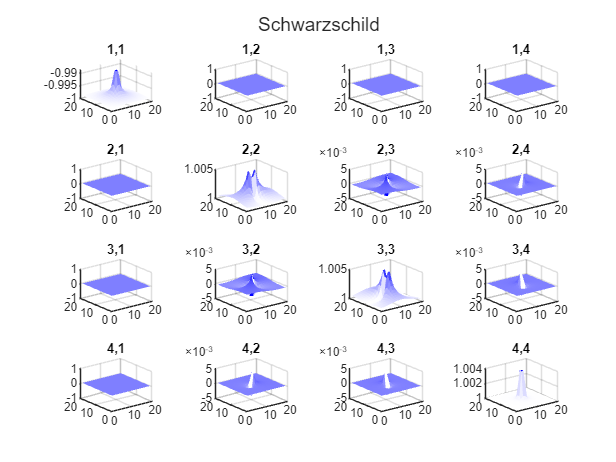

%% Schwarzschild
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
rs = 0.01;
Metric = metricGet_Schwarzschild(gridSize,worldCenter,rs);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name)

## Warp Metrics - Time Dependent

These warp metrics move through the space. For a proper evaluation of the stress-energy tensor in warp factory, a minimum of 5 time steps must be instanced. Comoving metrics in the next section is preferred for most analyses since only 1 time slice is needed.

### Alcubierre - Time Dependent

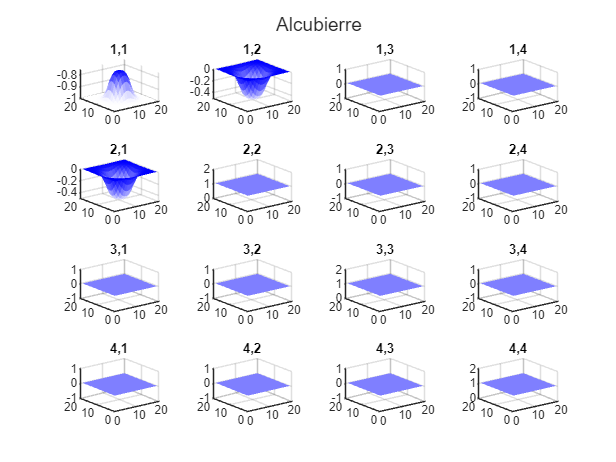

%% Alcubierre
gridSize = [5 20 20 20]; % Note the time size of 5
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_Alcubierre(gridSize,worldCenter,velocity,R,sigma);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(3,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name)

### Van Den Broeck - Time Dependent

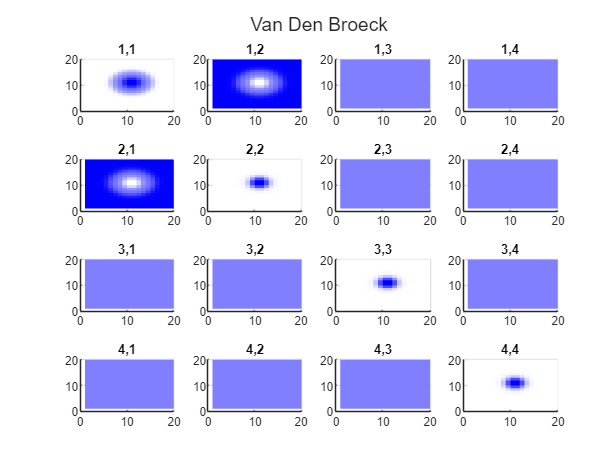

%% Van Den Broeck
gridSize = [5 20 20 20]; % Note the time size of 5
worldCenter = (gridSize+1)./2;
velocity = 0.1;
R1 = 2;
sigma1 = 1;
R2 = 5;
sigma2 = 1;
alpha = 0.5;
Metric = metricGet_VanDenBroeck(gridSize,worldCenter,velocity,R1,sigma1,R2,sigma2,alpha);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(3,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        view(2)
    end
end
sgtitle(Metric.name)

### Lentz - Time Dependent

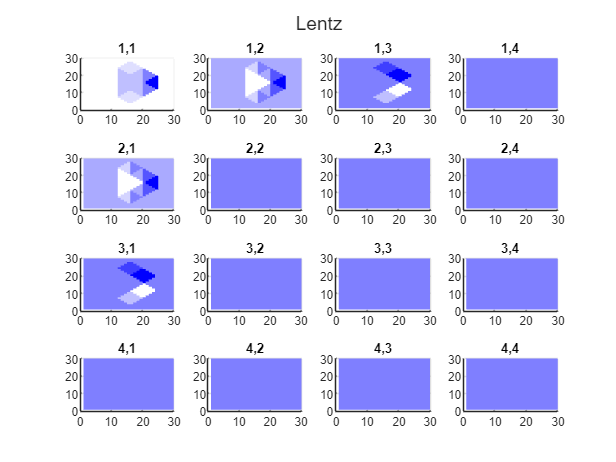

%% Lentz
gridSize = [5 30 30 2];  % Note the time size of 5, trailing size must be at least 2
worldCenter = (gridSize+1)./2;
velocity = 0.1;
Metric = metricGet_Lentz(gridSize,worldCenter,velocity);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(3,:,:,1),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        view(2)
    end
end
sgtitle(Metric.name)

## Warp Metrics - Comoving

These warp metrics do not move through the space, hence the name 'comoving'. For a proper evaluation of the stress-energy tensor in warp factory, only 1 time slice is needed since the metric is time-invariant.

### Alcubierre - Comoving

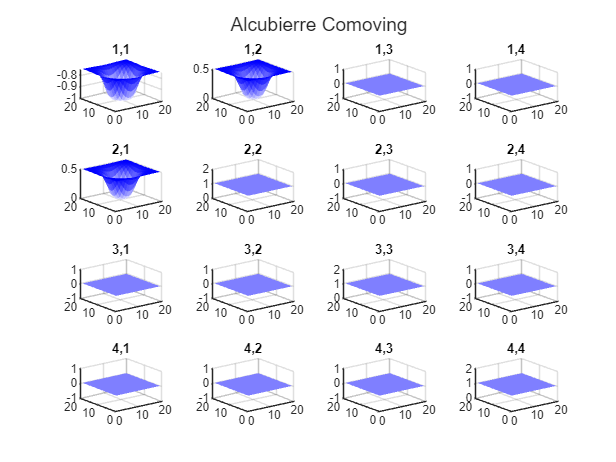

%% Alcubierre
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_AlcubierreComoving(gridSize,worldCenter,velocity,R,sigma);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
    end
end
sgtitle(Metric.name)

### Van Den Broeck - Comoving

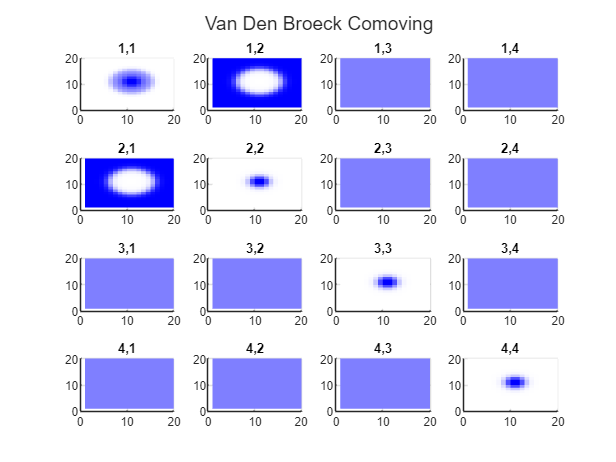

%% Van Den Broeck
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.1;
R1 = 2;
sigma1 = 1;
R2 = 5;
sigma2 = 1;
alpha = 0.5;
Metric = metricGet_VanDenBroeckComoving(gridSize,worldCenter,velocity,R1,sigma1,R2,sigma2,alpha);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,round(worldCenter(4))),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        view(2)
    end
end
sgtitle(Metric.name)

### Lentz - Comoving

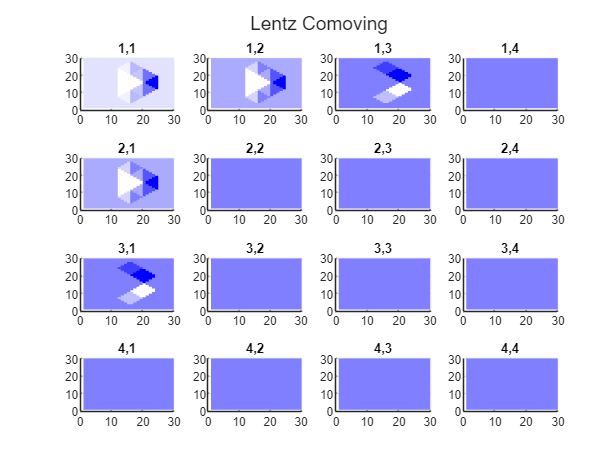

%% Lentz
gridSize = [1 30 30 2]; % Trailing size must be at least 2
worldCenter = (gridSize+1)./2;
velocity = 0.1;
Metric = metricGet_LentzComoving(gridSize,worldCenter,velocity);

% Plotting
clf
for i = 1:4
    for j = 1:4
        h = nexttile;
        surfq(Metric.tensor{i,j}(1,:,:,1),'EdgeColor','none')
        title(num2str(i) + "," + num2str(j))
        view(2)
    end
end
sgtitle(Metric.name)

### Warp Shell - Comoving

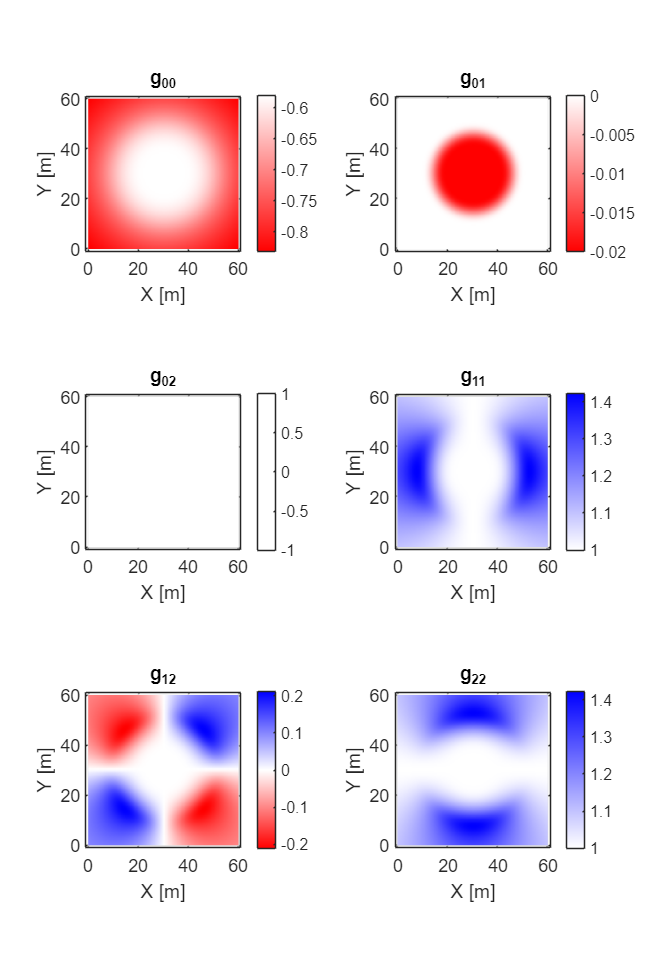

%%
width = 800;
height = 700;

figSize6 = [150,150,width,1.7*height];
textSize = 12;

%% Shell Metric
spaceScale = 2;
timeScale = 1;
tryGPU = 1;
centered = 1;
cartoonThickness = 5;


R1 = 10;
Rbuff = 0;
R2 = 20;

if centered == 1
    gridSize = ceil([1,2*(R2+10)*spaceScale,2*(R2+10)*spaceScale,cartoonThickness]);
else
    gridSize = ceil([1,(R2+10)*spaceScale,(R2+10)*spaceScale,cartoonThickness]);
end

factor = 1/3;
m = R2/(2*G)*c^2*factor;

vWarp = 0.02; % in betas

sigma = 0;
doWarp = 1;

gridScaling = [1/(timeScale*spaceScale*((vWarp)*c+1)),1/spaceScale,1/spaceScale,1/spaceScale];
gridScaling(1) = 1/(1000*c);
if centered == 1
    worldCenter = [(cartoonThickness+1)/2,(2*(R2+10)*spaceScale+1)/2,(2*(R2+10)*spaceScale+1)/2,(cartoonThickness+1)/2].*gridScaling;
else
    worldCenter = [(cartoonThickness+1)/2,5,5,(cartoonThickness+1)/2].*gridScaling;
end

if centered == 1
    x = linspace(0,2*(R2+10),gridSize(2)-4)';
    y = linspace(0,2*(R2+10),gridSize(3)-4)';
else
    x = linspace(0,(R2+10),gridSize(2)-4)';
    y = linspace(0,(R2+10),gridSize(3)-4)';
end

[X,Y] = meshgrid(x,y);

if centered == 1
    xlimit = [0 2*(R2+10)];
else
    xlimit = [0 (R2+10)];
end


smoothFactor = 4000;

[Metric_ConstantWarp] = metricGet_WarpShellComoving(gridSize,worldCenter,m,R1,R2,Rbuff,sigma,smoothFactor,vWarp,doWarp,gridScaling);

% Plotting
zOffset = 0;
figure('Position',figSize6)
tensorNames = ["g_{00}", "g_{01}", "g_{02}", "g_{03}"; "","g_{11}","g_{12}","g_{13}"; "","","g_{22}","g_{23}"; "","","","g_{33}"];
c1 = [1 1 1 2 2 3];
c2 = [1 2 3 2 3 3];
for i = 1:length(c1)
    h=nexttile;
    toPlot = squeeze(Metric_ConstantWarp.tensor{c1(i),c2(i)}(1,3:end-2,3:end-2,round((end+1)/2+zOffset)))';
    surf(squeeze(X),squeeze(Y),toPlot,"EdgeAlpha",0)
    title(tensorNames(c1(i),c2(i)))
    xlabel('X [m]')
    ylabel('Y [m]')
    set(gcf,'Color','w')
    set(gca,'FontSize',textSize)
    colormap(h, redblue(toPlot));
    axis equal
    colorbar
    view(2)
    box on
    xlim([-2 (gridSize(2)+2)]./spaceScale)
    ylim([-2 (gridSize(3)+2)]./spaceScale)
end